# 讀取文件

clc;clear;
filename  = '1214.log';

AA = importdata(filename);
datalength=length(AA.data(:,1));
% datalength=length(AA(:,1));

[Hr, Min , Sec , Sec_4 , type , ch , ID , s , number , byte0 , byte1 , byte2 , byte3 , byte4 , byte5 , byte6 , byte7]...
=textread(filename,'%d %d %d %d %s %d %d %s %d %d %d %d %d %d %d %d %d',datalength-20,'headerlines',20);



# CMD - ID 300

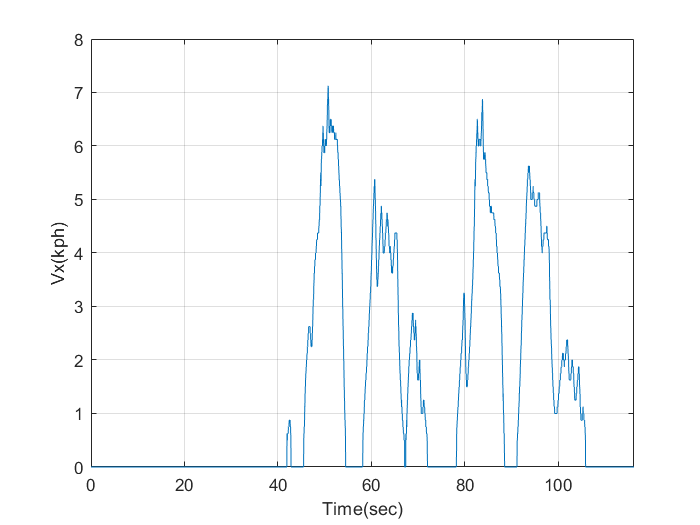

ID300=0; %%該ID量測到幾次的計數器

%--------------------------------------------------------------------

Factor_Offset_Driving_Tq=[0.1 0];

for i=1:length(ID)   % 提取時間以及該數據對應的byte
    if ID(i)==300
        ID300=ID300+1;
        Time300(ID300,1)=(Min(i)*60*10000+Sec(i)*10000+Sec_4(i))/10000;%%取出時間
        Driving_Tq_data(ID300,1)=byte7(i);
        Driving_Tq_data(ID300,2)=byte6(i);
    end
end

for j=1:length(Driving_Tq_data) %%十進轉二進再合併再轉十進
    A1=num2str(str2num(dec2bin(Driving_Tq_data(j,1))),'%08d');
    A2=num2str(str2num(dec2bin(Driving_Tq_data(j,2))),'%08d');
    A=[A2,A1];
    Driving_Tq(j)=bin2dec(A)*Factor_Offset_Driving_Tq(1)+Factor_Offset_Driving_Tq(2);
end

%--------------------------------------------------------------------

Factor_Offset_Brake_Pressor_F=[0.01 0];

for i=1:length(ID)   % 提取時間以及該數據對應的byte
    if ID(i)==300
        ID300=ID300+1;
        Time300(ID300,1)=(Min(i)*60*10000+Sec(i)*10000+Sec_4(i))/10000;%%取出時間
        Brake_Pressor_F_data(ID300,1)=byte5(i);
    end
end

for j=1:length(Brake_Pressor_F_data) %%十進轉二進再合併再轉十進
    A=num2str(str2num(dec2bin(Brake_Pressor_F_data(j,1))),'%08d');
    Brake_Pressor_F(j)=bin2dec(A)*Factor_Offset_Brake_Pressor_F(1)+Factor_Offset_Brake_Pressor_F(2);
end

%--------------------------------------------------------------------

Factor_Offset_Brake_Pressor=[0.01 0];

for i=1:length(ID)   % 提取時間以及該數據對應的byte
    if ID(i)==300
        ID300=ID300+1;
        Time300(ID300,1)=(Min(i)*60*10000+Sec(i)*10000+Sec_4(i))/10000;%%取出時間
        Brake_Pressor_data(ID300,1)=byte5(i);
    end
end

for j=1:length(Brake_Pressor_data) %%十進轉二進再合併再轉十進
    A=num2str(str2num(dec2bin(Brake_Pressor_data(j,1))),'%08d');
    Brake_Pressor(j)=bin2dec(A)*Factor_Offset_Brake_Pressor(1)+Factor_Offset_Brake_Pressor(2);
end

%--------------------------------------------------------------------

Factor_Offset_Steer_Ang=[0.01 0];

for i=1:length(ID)   % 提取時間以及該數據對應的byte
    if ID(i)==300
        ID300=ID300+1;
        Time300(ID300,1)=(Min(i)*60*10000+Sec(i)*10000+Sec_4(i))/10000;%%取出時間
        Steer_Ang_data(ID300,1)=byte3(i);
    end
end

for j=1:length(Steer_Ang_data) %%十進轉二進再合併再轉十進
    A=num2str(str2num(dec2bin(Steer_Ang_data(j,1))),'%08d');
    Steer_Ang(j)=bin2dec(A)*Factor_Offset_Steer_Ang(1)+Factor_Offset_Steer_Ang(2);
end

%--------------------------------------------------------------------



# Recieve - ID 301

# Plot

StartTime=Time300(1);%%定義想觀察的起始時間
StopTime=Time300(end);%%定義想觀察的結束時間


figure(2)
plot(Time300-StartTime,Steer_Ang);hold on
xlim([0 StopTime-StartTime]);
xlabel('Time(sec)')
ylabel('Vx(kph)')
grid;
hold off